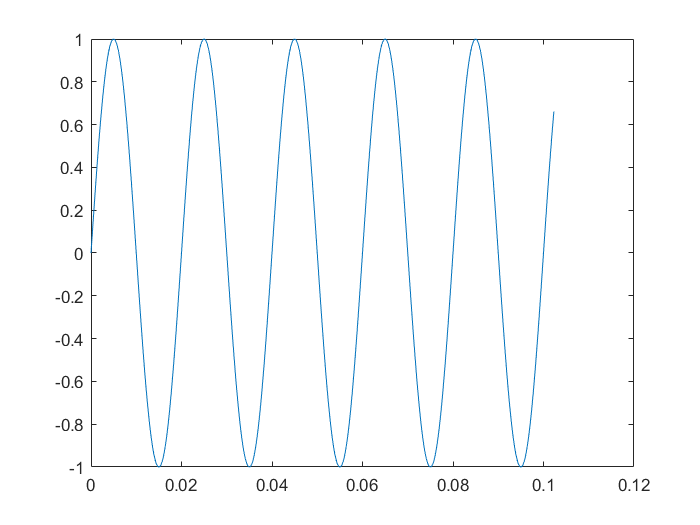

clc;clear all;close all;
% -------------------------------demo--------------------------------------%
% To show the complete process of digital signal processing system designing
% -------------------------------------------------------------------------%

%% 数字信号处理采样参数
N = 1024;%数据采样长度，采样时钟
Fs = 10000;%数字信号采样频率
Ts = 1/Fs;%Sampling time

%% 理想连续信号经过数字采样输入系统进行运算
A = 1;%Amplitude
t = (0:N-1)*Ts;%Time(s)
f = 50;%Frequency(Hz)
n = Fs/f;%Data length of a period
x = A * sin(2*pi*f*t);%Input signal
plot(t,x);

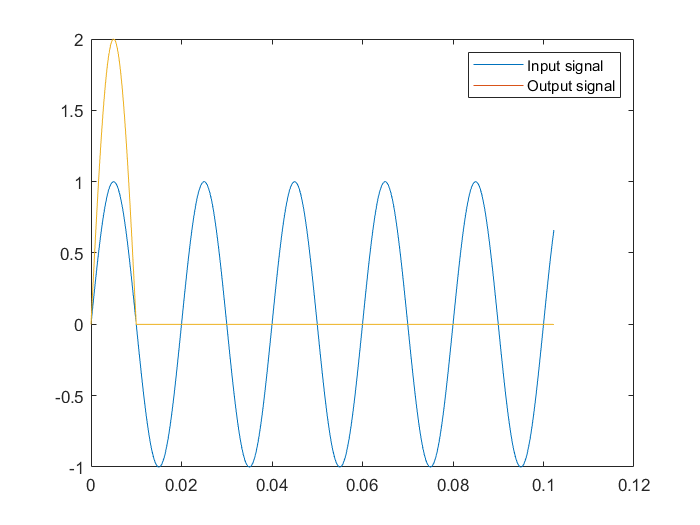


%% Multiply,Add and Delay
C = 2;%Multiplier
D = n/2;%Delay,half of period

% y_0 = C * x;
y_0 = zeros(1,N);%设置空数组，获得内存
y_1 = zeros(1,N);%设置空数组，获得内存
y = zeros(1,N);
for i = 1:N
    y_0(i) = C * x(i);
    if(i>D)%判断是否可以延迟
        y_1(i) = y_0(i-D);%延迟
    end
    y(i) = y_0(i) + y_1(i);%Output signal
end
hold on%当前要绘制的图基于上一张图
plot(t,y);
legend('Input signal','Output signal');

%设置数据传入simulink
x_in(:,1) = 1:N;%x_in第一列传入时钟长度
x_in(:,2) = x;%x_in第二列传入数据
